clear; close all; 
% Data Generating
% data_diff
[y,Fs] = audioread('Data/genres_original/country/country.00001.wav');
N = length(y);
N1 = floor(N/3);
y = y(1:N1);
playerObj = audioplayer(y, Fs);
% play(playerObj);

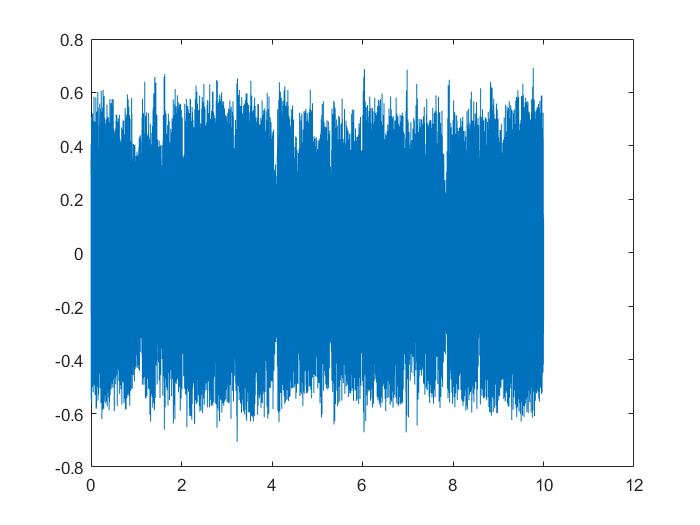

% FFT
plot((0:N1-1)/(Fs), y);

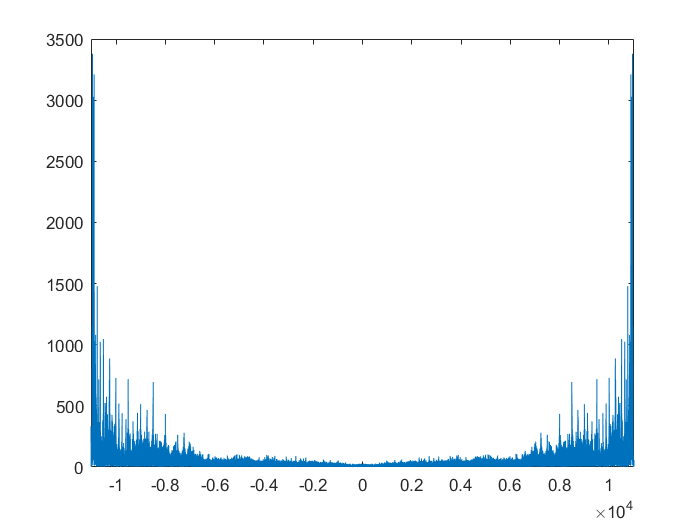

Y = fft(y);
plot(Fs*(-N1/2:N1/2-1)/N1, abs(Y));
xlim([Fs*(-N1/2)/N1, Fs*(N1/2-1)/N1]);

% % Octave-Scale Filter
% oct_alpha = 0.02;  % tunable
% oct_diff_norm = oct_diff/(Fs/2);  % Normalized interval
% sc = zeros(7,1); valley = zeros(7,1); peak = zeros(7,1);
% for i = 1 : length(oct_diff_norm)-1
%     [peak(i), sc(i), valley(i)] = oct_feature(oct_diff_norm(i), oct_diff_norm(i+1), Y(N1/2:end), oct_alpha);
% end

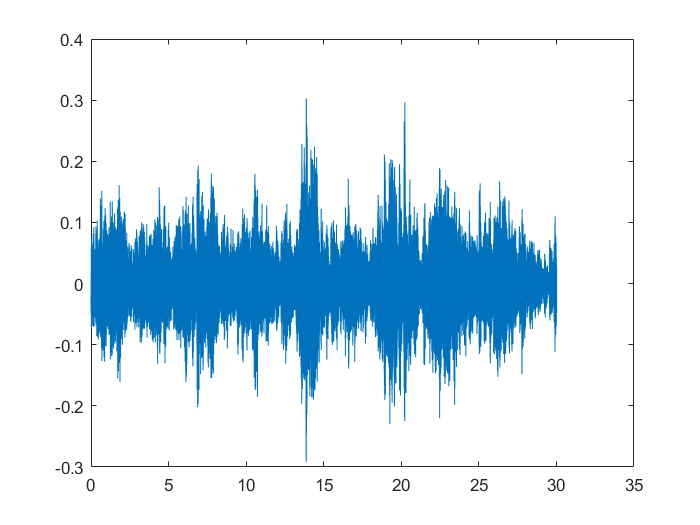

clear; close all;
[y,Fs] = audioread('Data/genres_original/classical/classical.00000.wav');
y = y(1:4:end);
N = length(y);
playerObj = audioplayer(y, Fs/4);
% play(playerObj);
plot((0:N-1)/(Fs/4), y);

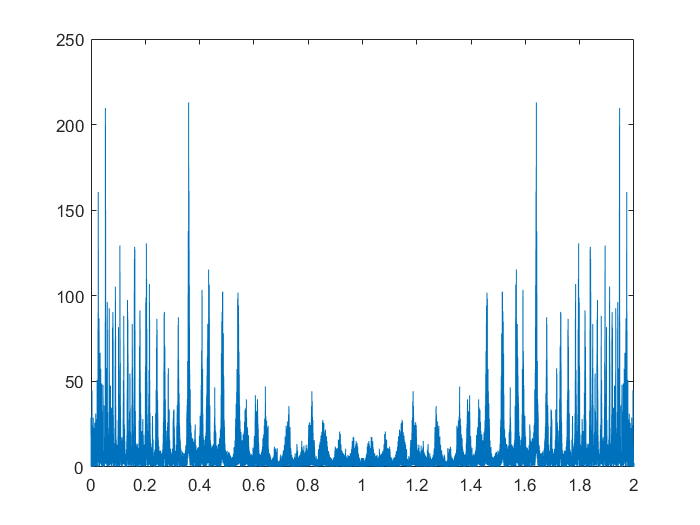

Y = fft(y);
plot(2*(0:N-1)/N, abs(Y));

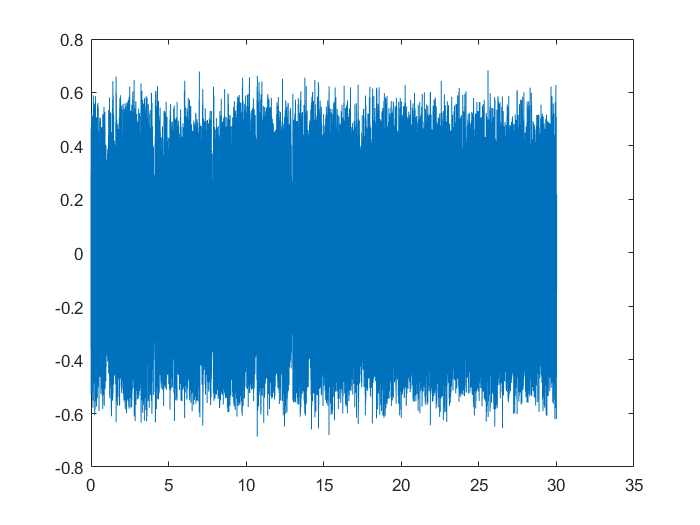

clear; close all;
[y,Fs] = audioread('Data/genres_original/country/country.00001.wav');
y = y(1:4:end);
N = length(y);
playerObj = audioplayer(y, Fs/4);
% play(playerObj);
plot((0:N-1)/(Fs/4), y);

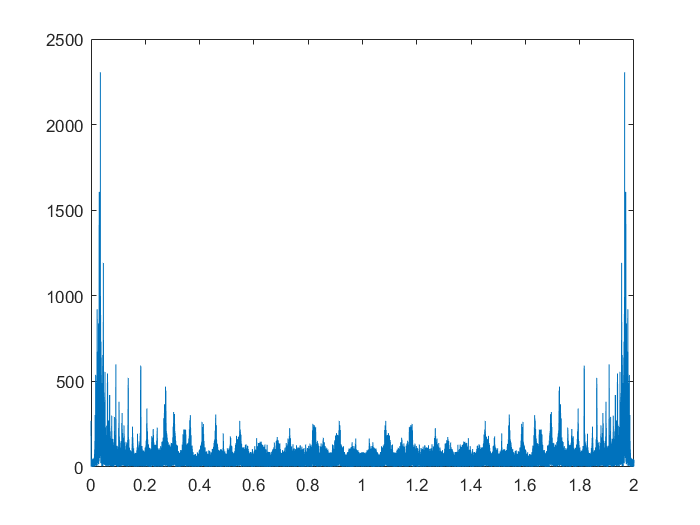

Y = fft(y);
plot(2*(0:N-1)/N, abs(Y));

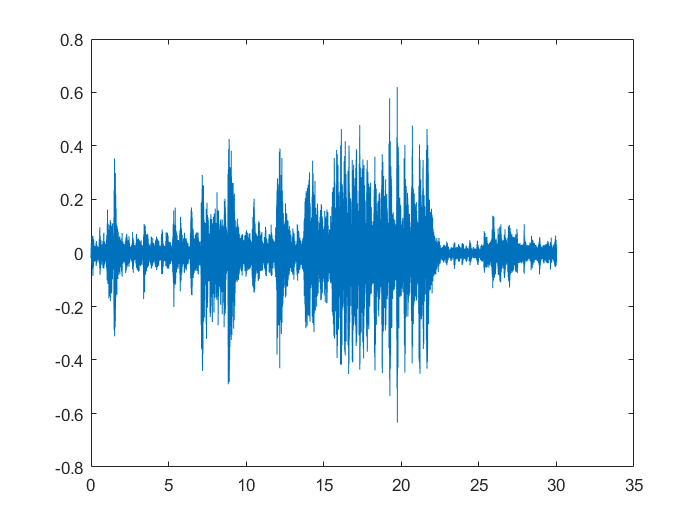

clear; close all;
[y,Fs] = audioread('Data/genres_original/jazz/jazz.00000.wav');
y = y(1:4:end);
N = length(y);
playerObj = audioplayer(y, Fs/4);
% play(playerObj);
plot((0:N-1)/(Fs/4), y);

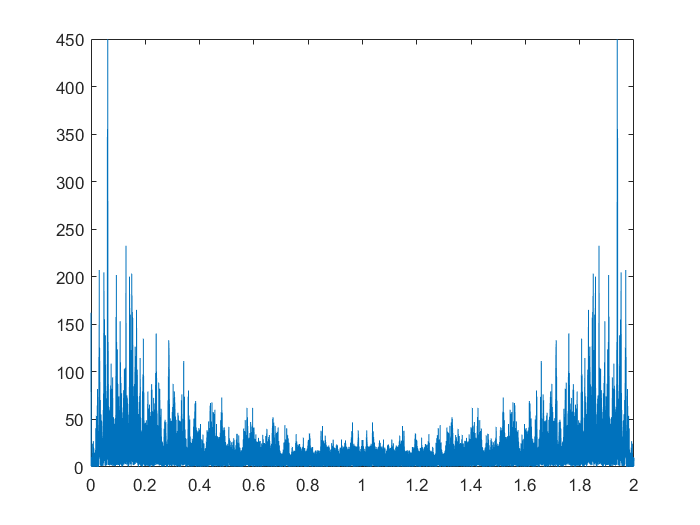

Y = fft(y);
plot(2*(0:N-1)/N, abs(Y));

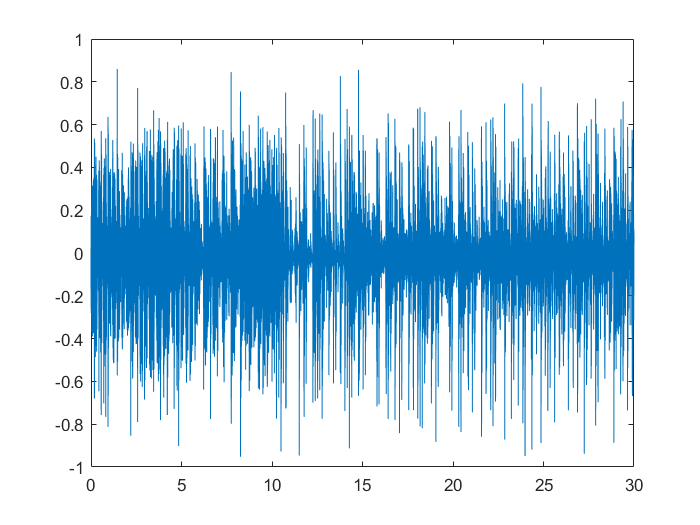

clear; close all;
[y,Fs] = audioread('Data/genres_original/hiphop/hiphop.00000.wav');
y = y(1:4:end);
N = length(y);
playerObj = audioplayer(y, Fs/4);
% play(playerObj);
plot((0:N-1)/(Fs/4), y);

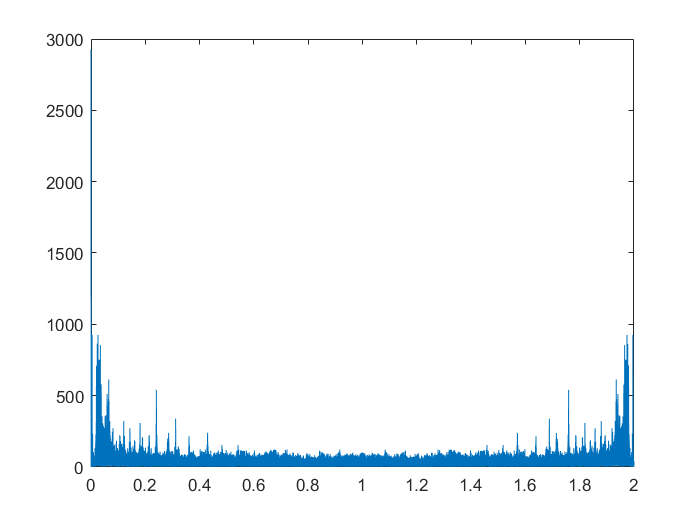

Y = fft(y);
plot(2*(0:N-1)/N, abs(Y));

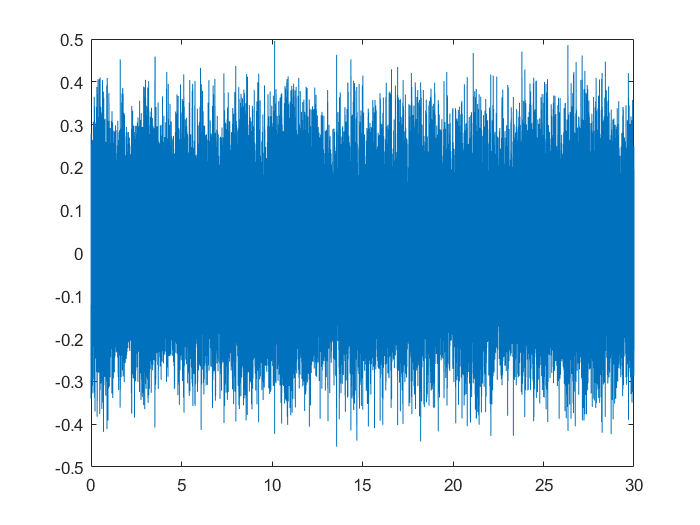

clear; close all;
[y,Fs] = audioread('Data/genres_original/metal/metal.00000.wav');
y = y(1:4:end);
N = length(y);
playerObj = audioplayer(y, Fs/4);
% play(playerObj);
plot((0:N-1)/(Fs/4), y);

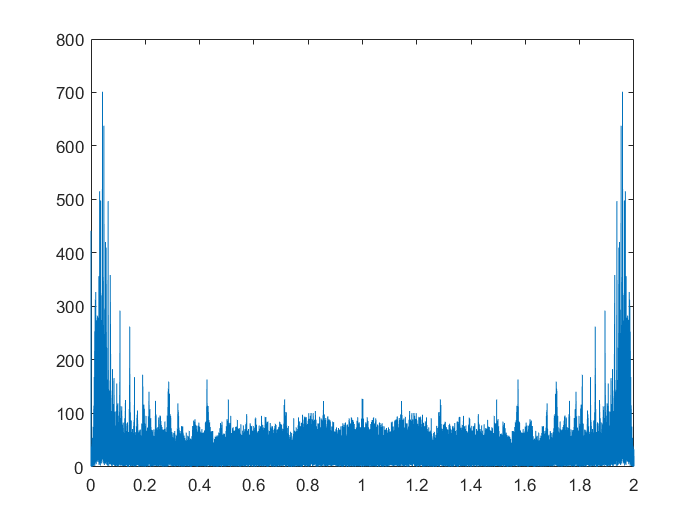

Y = fft(y);
plot(2*(0:N-1)/N, abs(Y));